# Gabriel Colangelo

clear
close all
clc

## Problem 1a - i)

Find: type, $$a,e,r_D,v_D,\gamma_D, \theta^*_D, r_A, v_A, \gamma_A, |\Delta \bar{v}_D|, \alpha_D, |\Delta \bar{v}_A|, \alpha_A$

Assume: TA = 260, TOF = 8 hours, initial circular orbit radius of 2 Earth radii and a final circular orbit radii of 6.6 Earth Radii. Coplanar Orbit

% Earth Parameters
mu_earth    = 398600.4415;
R_earth     = 6378.1363;

% Orbit radii
r1          = 2*R_earth;
r2_A        = 6.6*R_earth;

% Transfer angle
TA_A        = 260;

% Time of flight
TOF_A       = 8*3600;

% Call function to solve Lamberts Problem
probA       = LambertsProblem(TOF_A, r1, r2_A, TA_A, mu_earth);
fprintf('The semi major axis of the transfer orbit is %.4E km',probA.a)

The semi major axis of the transfer orbit is 2.6822E+04 km


$$\phi = 360 - TA = 100 \ [deg]\\
\text{Law of cosines from space triangle: } \ c^2 = r_1^2 + r_2^2 - 2r_1r_2\cos{\phi} \\
\text{Semi-perimeter: } \ s = (r_1 + r_2 + c)/2\\
\text{Minimum energy semi major axis} \ a_{min} =  s/2 = 2.5227 \times 10^4 \ [km] \\
\beta_{min} = 2\sin^{-1}{\sqrt{\frac{s-c}{2a_{min}}} = 34.3 \ [deg]\\
TOF_{min} = \sqrt{\frac{a^3}{\mu}}[(\pi - \beta_{min} ) - (\sin{\pi} - \sin{\beta_{min}})] = 5.47 \ [hour]
$$


**The transfer angle is greater than 180 degrees, therefore the transfer type is a 2. The minimum energy time of flight is less than the desired time of flight, therefore the transfer type is a B. The transfer type is ****2B.**

For a type 2B, the true $\alpha$ and $\beta$ values are related to their principal values through:


$$\alpha = 2\pi - \alpha_0\\
\beta = -\beta_0$$


Lamberts problem is solved numerically for $a$ using a bisection method:


$$\beta_0= 2\sin^{-1}{\sqrt{\frac{s-c}{2a}} \\
\alpha_0= 2\sin^{-1}{\sqrt{\frac{s}{2a}} \\
TOF = \sqrt{\frac{a^3}{\mu}}[(\alpha - \beta ) - (\sin{\alpha} - \sin{\beta})] = 8\ [hour] \\
\\
\underline{\mathbf{a = 26822.00 \ [km]}}$$


% Calculate semi latus rectum
p_A     = max((4*probA.a*(probA.s - r1)*(probA.s - r2_A)/probA.c^2)*...
          [sin((probA.alpha + probA.beta)/2)^2, sin((probA.alpha - probA.beta)/2)^2]);

% Calculate eccentricity
e_A     = sqrt(1 - p_A/probA.a);
fprintf('The transfer eccentricity is %.4f ',e_A)

The transfer eccentricity is 0.6379 


$$\alpha  = 208.26 \ [deg] \\
\beta = -33.27 \ [deg] \\
p = a(1 - e^2) = \frac{4a(s-r_1)(s-r_2)}{c^2}\sin^2{(\frac{\alpha \pm \beta}{2})} = 15906.8 \ \text{or} \ 11771.2 \ [km]\\
\bar{OF} = 2ae$$


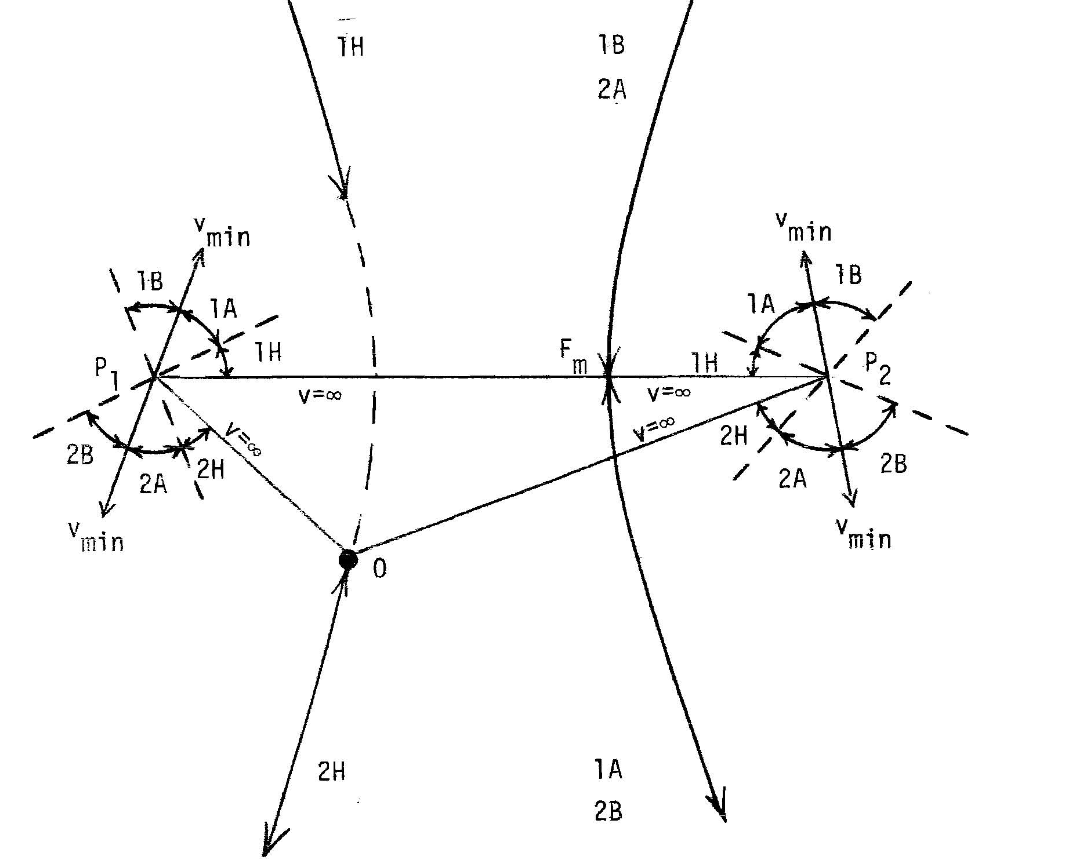

For 2B transfer type, a smaller e is needed as observed in the solution space diagram above. A smaller e will cause an increase in semi-latus rectum. Therefore, the necessary semi-latus rectum value is the larger option (15906.8 [km]).


$$e = \sqrt{1 - \frac{p}{a}} \\
\\
\mathbf{e = 0.6379}$$



$$\text{ At departure: } \  r_D = r_1 = 2 \ [ R_{Earth}]\\
\mathbf{r_D = 12756.2726 \ [km]}$$


% Calculate energy of transfer ellipse
energy_A    = -mu_earth/(2*probA.a);

% Velocity magnitude at departure
v1_A        = sqrt(2*(energy_A + mu_earth/r1));
fprintf('The velocity at departure on the transfer ellipse is %.3f km/s',v1_A)

The velocity at departure on the transfer ellipse is 6.902 km/s


$$v_D = \sqrt{2(\frac{\mu}{r_D} - \frac{\mu}{2 a})}\\
v_D = 6.902 \ [km/s]$$


% Calculate true anomaly at departure
true_anomaly1_A     = -acosd((p_A/r1 - 1)/e_A);

% Calculate true anomaly at arrival
true_anomaly2_A     = -acosd((p_A/r2_A - 1)/e_A);


$$\theta^* = \cos^{-1}{(\frac{1}{e_m}(\frac{p}{r} - 1))} \\
\theta^*_D = \pm 67.22 \ [deg] \\
\theta^*_A = \pm 167.22 \ [deg] \\
\text{4 possible combinations of $\theta^*_A$ and $\theta^*_D$. However, only one pair produces a transfer angle of 260 deg.}\\
\text{Therefore, the pair of true anomaly's must be:} \\
\\
\theta^*_D = -67.22 \ [deg]  = 292.77 \ [deg]\\
\theta^*_A = -167.22 \ [deg]  = 192.77 \ [deg]\\$$


% Minimum energy transfer specific angular momentum
h_A         = sqrt(mu_earth*p_A);

% Flight path angle at departure
gamma1_A    = sign(true_anomaly1_A)*acosd(h_A/(r1*v1_A));
fprintf('The flight path angle at departure is %.3f deg',gamma1_A)

The flight path angle at departure is -25.252 deg


$$h = \sqrt{\mu p}\\
h = r_Dv_D\cos{\gamma_D}\\
\\
\gamma_D = -25.25 \ [deg] \ \ \text{Descending based on $\theta^*_D$, so $\gamma$ < 0}$$



$$\text{ At arrival: } \  r_A = r_2 = 6.6 \ [ R_{Earth}]\\
\mathbf{r_A = 42095.69958 \ [km]}$$


% Velocity magnitude at arrival
v2_A        = sqrt(2*(energy_A + mu_earth/r2_A));
fprintf('The velocity at arrival on the transfer ellipse is %.3f km/s',v2_A)

The velocity at arrival on the transfer ellipse is 2.019 km/s


$$v_A = \sqrt{2(\frac{\mu}{r_A} - \frac{\mu}{2 a})}\\
v_A = 2.019 \ [km/s]$$


% Flight path angle at arrival
gamma2_A    = sign(true_anomaly2_A)*acosd(h_A/(r2_A*v2_A));
fprintf('The flight path angle at arrival is %.3f deg',gamma2_A)

The flight path angle at arrival is -20.475 deg


$$h = \sqrt{\mu p}\\
h = r_Av_A\cos{\gamma_A}\\
\\
\gamma_A = -20.475 \ [deg] \ \ \text{Descending based on $\theta^*_A$, so $\gamma$ < 0}$$


% Departure velocity vector - orbit frame
v1_vec_A    = [v1_A*sind(gamma1_A);v1_A*cosd(gamma1_A)];

% Initial circular orbit velocity
vc1         = sqrt(mu_earth/r1);

% Departure deltaV 
dv1_A       = norm(v1_vec_A - [0;vc1]);
fprintf('The departure deltaV magnitude is %.4f km/s',dv1_A)

The departure deltaV magnitude is 3.0157 km/s


$$\bar{v}_D = v_D\sin{\gamma_D} \ \hat{r} + v_D\cos{\gamma_D} \ \hat{\theta} \\

\bar{v}_{c,1} = \sqrt{\frac{\mu}{r_D}}\ \hat{\theta} = 5.59 \ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_D = \bar{v}_D - \bar{v}_{c,1} = -2.944 \ \hat{r} + 0.652\ \hat{\theta} \ [km/s]\\
\\
|\Delta \bar{v}_D | = 3.0157 \ [km/s]$$


% Arrival  velocity vector - orbit frame
v2_vec_A    = [v2_A*sind(gamma2_A);v2_A*cosd(gamma2_A)];

% Final circular orbit velocity
vc2_A       = sqrt(mu_earth/r2_A);

% Arrival deltaV 
dv2_A       = norm([0;vc2_A] - v2_vec_A);
fprintf('The arrival deltaV magnitude is %.4f km/s',dv2_A)

The arrival deltaV magnitude is 1.3800 km/s


$$\bar{v}_A = v_A\sin{\gamma_A} \ \hat{r} + v_A\cos{\gamma_A} \ \hat{\theta} \\

\bar{v}_{c,2} = \sqrt{\frac{\mu}{r_A}}\ \hat{\theta} = 3.077 \ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_A = \bar{v}_{c,2} - \bar{v}_A  = 0.7062 \ \hat{r} + 1.185\ \hat{\theta} \ [km/s]\\
\\
|\Delta \bar{v}_A | = 1.38 \ [km/s]$$


% Departure change in FPA, initial FPA is zero (circular orbit)
deltaFPA1_A     =  gamma1_A - 0;

% Law of sines, calculate beta (must be greater than 90)
beta1_A         = 180 - asind(v1_A*sind(abs(deltaFPA1_A))/dv1_A);

% Can also use angle between to vectors to get alpha directly
% acosd(dot([0;vc1],v1_vec_A - [0;vc1])/(dv1_A*vc1))

% Departure maneuver alpha
alpha1_A        = sign(deltaFPA1_A)*(180 - beta1_A);
fprintf('The departure maneuver alpha is %.3f deg',alpha1_A)

The departure maneuver alpha is -77.509 deg


$$\text{Law of sines:} \ \frac{\Delta v_D}{\sin{|\Delta \gamma_D}|} = \frac{v_D}{\sin{\beta}} \\

\beta = 77.51, 102.49 \ [deg] \\

\text{$v_D^2 > \Delta v_D^2 + v_{c,1}^2$, therefore $\beta  > 90$,  $\beta  = 102.49$}\\
\beta_D = 180 - |\alpha_D| \\
\\
\alpha_D = -77.509 \ [deg] \ \ \text{ Negative due to decrease in $\gamma$, \ $\Delta \gamma_D = \gamma_D - \gamma_1< 0$}$$


% Arrival change in FPA, final FPA is zero (circular orbit)
deltaFPA2_A     =  0 - gamma2_A;

% Law of sines, calculate beta (must be greater than 90)
beta2_A         = 180 - asind(vc2_A*sind(abs(deltaFPA2_A))/dv2_A);

% Can also use angle between to vectors to get alpha directly
% acosd(dot([0;vc2_A] - v2_vec_A,v2_vec_A)/(v2_A*dv2_A))

% Arrival maneuver alpha
alpha2_A        = sign(deltaFPA2_A)*(180 - beta2_A);
fprintf('The arrival maneuver alpha is %.3f deg',alpha2_A)

The arrival maneuver alpha is 51.258 deg


$$\text{Law of sines:} \ \frac{\Delta v_A}{\sin{|\Delta \gamma_A}|} = \frac{v_{c,2}}{\sin{\beta}} \\

\beta = 51.25, 128.74 \ [deg] \\

\text{$v_{c,2}^2 > \Delta v_A^2 + v_A^2$, therefore $\beta  > 90$,  $\beta  = 128.74$}\\
\beta= 180 - |\alpha_A| \\
\\
\alpha_A = 51.258 \ [deg] \ \ \text{ Positive due to increase in $\gamma$, \ $\Delta \gamma_A =  \gamma_2 - \gamma_A > 0$}$$


% Departure deltaV in VNC frame - beta is 0, coplanar maneuevr
dv1_VC_A    = dv1_A*[cosd(0)*cosd(alpha1_A), cosd(0)*sind(alpha1_A)];

% Arrival deltaV in VNC frame - beta is 0, coplanar maneuevr
dv2_VC_A    = dv2_A*[cosd(0)*cosd(alpha2_A), cosd(0)*sind(alpha2_A)];

## Problem 1a - ii)

Find: Phase angle between the vehicles at departure

% Mean motion of satellite about earth
n2_A        = sqrt(mu_earth/r2_A^3);

% Calculate phase angle of satellite at depature
phase_A     = (TA_A*pi/180 - n2_A*TOF_A)*180/pi;
fprintf('The phase angle at departure is %.2f deg',phase_A)

The phase angle at departure is 139.38 deg


$$n_{sat} = \sqrt{\frac{\mu_{earth}}{r_A^3}} \ \text{mean motion of satellite in  circular orbit} \\
(n_{sat})(T.O.F) = 260 - \phi \\
\\
\phi = 139.38 \ [deg] \ \ \ \text{Phase angle at departure}$$


## Problem 1a - iv)

**The transfer path does pass through periapsis**, as the initial true anomaly on the path is descending towards periapsis, and the transfer angle is 260 degrees. Therefore, a passage through periapsis must occur. **There is not an issue **because the distance to periapis is $r_p = a(1-e) = 9711.55 \ [km]$, which is greater than the radius of the Earth. The closest passage is at an altitude of 3,333 [km].

## Problem 1b - i)

Find: type, $$a,e,r_D,v_D,\gamma_D, \theta^*_D, r_A, v_A, \gamma_A, |\Delta \bar{v}_D|, \alpha_D, |\Delta \bar{v}_A|, \alpha_A$

Assume: TA = 120, TOF = 1.45 hours, initial circular orbit radius of 2 Earth radii and a final circular orbit radii of 4 Earth Radii. Coplanar Orbit

% Final circular orbit radii
r2_B        = 4*R_earth;

% Transfer angle
TA_B        = 120;

% Time of flight
TOF_B       = 1.5*3600;

% Call function to solve Lamberts Problem
probB       = LambertsProblem(TOF_B, r1, r2_B, TA_B, mu_earth);
fprintf('The semi major axis of the transfer orbit is %.4E km',probB.a)

The semi major axis of the transfer orbit is 8.2734E+04 km


$$\phi = TA = 120 \ [deg]\\
\text{Law of cosines from space triangle: } \ c^2 = r_1^2 + r_2^2 - 2r_1r_2\cos{\phi} \\
\text{Semi-perimeter: } \ s = (r_1 + r_2 + c)/2\\
\text{Minimum energy semi major axis} \ a_{min} =  s/2 = 18004.68 \ [km] \\
\beta_{min} = 2\sin^{-1}{\sqrt{\frac{s-c}{2a_{min}}} = 29.01 \ [deg]\\
TOF_{min} = \sqrt{\frac{a^3}{\mu}}[(\pi - \beta_{min} ) - (\sin{\pi} - \sin{\beta_{min}})] = 3.32 \ [hour]
$$


**The transfer angle is less than 180 degrees, therefore the transfer type is a 1. The minimum energy time of flight is greater than the desired time of flight, therefore the transfer type is a A. The transfer type is ****1A.**

For a type 1A, the true $\alpha$ and $\beta$ values are related to their principal values through:


$$\alpha = \alpha_0\\
\beta = \beta_0$$


Lamberts problem is solved numerically for $a$ using a bisection method:


$$\beta_0= 2\sin^{-1}{\sqrt{\frac{s-c}{2a}} \\
\alpha_0= 2\sin^{-1}{\sqrt{\frac{s}{2a}} \\
TOF = \sqrt{\frac{a^3}{\mu}}[(\alpha - \beta ) - (\sin{\alpha} - \sin{\beta})] = 1.5\ [hour] \\
\\
\underline{\mathbf{a = 82734.26 \ [km]}}$$


% Calculate semi latus rectum
p_B     = max((4*probB.a*(probB.s - r1)*(probB.s - r2_B)/probB.c^2)*...
          [sin((probB.alpha + probB.beta)/2)^2, sin((probB.alpha - probB.beta)/2)^2]);

% Calculate eccentricity
e_B     = sqrt(1 - p_B/probB.a);
fprintf('The transfer eccentricity is %.4f ',e_B)

The transfer eccentricity is 0.8513 


$$\alpha  = 55.61 \ [deg] \\
\beta = 13.42 \ [deg] \\
p = a(1 - e^2) = \frac{4a(s-r_1)(s-r_2)}{c^2}\sin^2{(\frac{\alpha \pm \beta}{2})} = 22771.3 \ \text{or} \ 9187.6 \ [km]\\
\bar{OF} = 2ae$$


For 1A transfer type, a smaller e is needed as observed in the solution space diagram above. A smaller e will cause an increase in semi-latus rectum. Therefore, the necessary semi-latus rectum value is the larger option (22771.27 [km]).


$$e = \sqrt{1 - \frac{p}{a}} \\
\\
\mathbf{e = 0.8513}$$



$$\text{ At departure: } \  r_D = r_1 = 2 \ [ R_{Earth}]\\
\mathbf{r_D = 12756.2726 \ [km]}$$


% Calculate energy of transfer ellipse
energy_B    = -mu_earth/(2*probB.a);

% Velocity magnitude at departure
v1_B        = sqrt(2*(energy_B + mu_earth/r1));
fprintf('The velocity at departure on the transfer ellipse is %.3f km/s',v1_B)

The velocity at departure on the transfer ellipse is 7.595 km/s


$$v_D = \sqrt{2(\frac{\mu}{r_D} - \frac{\mu}{2 a})}\\
v_D = 7.595 \ [km/s]$$


% Calculate true anomaly at departure
true_anomaly1_B     = -acosd((p_B/r1 - 1)/e_B);

% Calculate true anomaly at arrival
true_anomaly2_B     = acosd((p_B/r2_B - 1)/e_B);


$$\theta^* = \cos^{-1}{(\frac{1}{e_m}(\frac{p}{r} - 1))} \\
\theta^*_D = \pm 22.75 \ [deg] \\
\theta^*_A = \pm 97.25 \ [deg] \\
\text{4 possible combinations of $\theta^*_A$ and $\theta^*_D$. However, only one pair produces a transfer angle of 120 deg.}\\
\text{Therefore, the pair of true anomaly's must be:} \\
\\
\theta^*_D = -22.75 \ [deg]  = 337.25 \ [deg]\\
\theta^*_A = 97.25 \ [deg]  \\$$


% Minimum energy transfer specific angular momentum
h_B         = sqrt(mu_earth*p_B);

% Flight path angle at departure
gamma1_B    = sign(true_anomaly1_B)*acosd(h_B/(r1*v1_B));
fprintf('The flight path angle at departure is %.3f deg',gamma1_B)

The flight path angle at departure is -10.449 deg


$$h = \sqrt{\mu p}\\
h = r_Dv_D\cos{\gamma_D}\\
\\
\gamma_D = -10.45 \ [deg] \ \ \text{Descending based on $\theta^*_D$, so $\gamma$ < 0}$$



$$\text{ At arrival: } \  r_A = r_2 = 4 \ [ R_{Earth}]\\
\mathbf{r_A = 25512.54 \ [km]}$$


% Velocity magnitude at arrival
v2_B        = sqrt(2*(energy_B + mu_earth/r2_B));
fprintf('The velocity at arrival on the transfer ellipse is %.3f km/s',v2_B)

The velocity at arrival on the transfer ellipse is 5.141 km/s


$$v_A = \sqrt{2(\frac{\mu}{r_A} - \frac{\mu}{2 a})}\\
v_A = 5.141 \ [km/s]$$


% Flight path angle at arrival
gamma2_B    = sign(true_anomaly2_B)*acosd(h_B/(r2_B*v2_B));
fprintf('The flight path angle at arrival is %.3f deg',gamma2_B)

The flight path angle at arrival is 43.416 deg


$$h = \sqrt{\mu p}\\
h = r_Av_A\cos{\gamma_A}\\
\\
\gamma_A = 43.416 \ [deg] \ \ \text{ascending based on $\theta^*_A$, so $\gamma$ > 0}$$


% Departure velocity vector - orbit frame
v1_vec_B    = [v1_B*sind(gamma1_B);v1_B*cosd(gamma1_B)];

% Departure deltaV 
dv1_B       = norm(v1_vec_B - [0;vc1]);
fprintf('The departure deltaV magnitude is %.4f km/s',dv1_B)

The departure deltaV magnitude is 2.3295 km/s


$$\bar{v}_D = v_D\sin{\gamma_D} \ \hat{r} + v_D\cos{\gamma_D} \ \hat{\theta} \\

\bar{v}_{c,1} = \sqrt{\frac{\mu}{r_D}}\ \hat{\theta} = 5.59 \ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_D = \bar{v}_D - \bar{v}_{c,1} = -1.377 \ \hat{r} + 1.878\ \hat{\theta} \ [km/s]\\
\\
|\Delta \bar{v}_D | = 2.3295 \ [km/s]$$


% Arrival  velocity vector - orbit frame
v2_vec_B    = [v2_B*sind(gamma2_B);v2_B*cosd(gamma2_B)];

% Final circular orbit velocity
vc2_B       = sqrt(mu_earth/r2_B);

% Arrival deltaV 
dv2_B       = norm([0;vc2_B] - v2_vec_B);
fprintf('The arrival deltaV magnitude is %.4f km/s',dv2_B)

The arrival deltaV magnitude is 3.5401 km/s


$$\bar{v}_A = v_A\sin{\gamma_A} \ \hat{r} + v_A\cos{\gamma_A} \ \hat{\theta} \\

\bar{v}_{c,2} = \sqrt{\frac{\mu}{r_A}}\ \hat{\theta} = 3.952 \ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_A = \bar{v}_{c,2} - \bar{v}_A  = -3.533 \ \hat{r} + 0.218 \ \hat{\theta} \ [km/s]\\
\\
|\Delta \bar{v}_A | = 3.54 \ [km/s]$$


% Departure change in FPA, initial FPA is zero (circular orbit)
deltaFPA1_B     =  gamma1_B - 0;

% Law of sines, calculate beta (must be greater than 90)
beta1_B         = 180 - asind(v1_B*sind(abs(deltaFPA1_B))/dv1_B);

% Can also use angle between to vectors to get alpha directly
% acosd(dot([0;vc1],v1_vec_B - [0;vc1])/(dv1_B*vc1))

% Departure maneuver alpha
alpha1_B        = sign(deltaFPA1_B)*(180 - beta1_B);
fprintf('The departure maneuver alpha is %.3f deg',alpha1_B)

The departure maneuver alpha is -36.247 deg


$$\text{Law of sines:} \ \frac{\Delta v_D}{\sin{|\Delta \gamma_D}|} = \frac{v_D}{\sin{\beta}} \\

\beta = 36.25, 143.75 \ [deg] \\

\text{$v_D^2 > \Delta v_D^2 + v_{c,1}^2$, therefore $\beta  > 90$,  $\beta  = 143.75$}\\
\beta_D = 180 - |\alpha_D| \\
\\
\alpha_D = -36.25 \ [deg] \ \ \text{ Negative due to decrease in $\gamma$, \ $\Delta \gamma_D = \gamma_D - \gamma_1< 0$}$$


% Arrival change in FPA, final FPA is zero (circular orbit)
deltaFPA2_B     =  0 - gamma2_B;

% Law of sines, calculate beta (must be greater than 90)
beta2_B         = asind(vc2_B*sind(abs(deltaFPA2_B))/dv2_B);

% Can also use angle between to vectors to get alpha directly
% acosd(dot([0;vc2_B] - v2_vec_B,v2_vec_B)/(v2_B*dv2_B))

% Arrival maneuver alpha
alpha2_B        = sign(deltaFPA2_B)*(180 - beta2_B);
fprintf('The arrival maneuver alpha is %.3f deg',alpha2_B)

The arrival maneuver alpha is -129.879 deg


$$\text{Law of sines:} \ \frac{\Delta v_A}{\sin{|\Delta \gamma_A}|} = \frac{v_{c,2}}{\sin{\beta}} \\

\beta = 50.12, 129.88 \ [deg] \\

\text{$v_{c,2}^2 < \Delta v_A^2 + v_A^2$, therefore $\beta  < 90$,  $\beta  = 50.12$}\\
\beta= 180 - |\alpha_A| \\
\\
\alpha_A = -129.88 \ [deg] \ \ \text{ Negative due to decrease in $\gamma$, \ $\Delta \gamma_A =  \gamma_2 - \gamma_A < 0$}$$


% Departure deltaV in VNC frame - beta is 0, coplanar maneuevr
dv1_VC_B    = dv1_B*[cosd(0)*cosd(alpha1_B), cosd(0)*sind(alpha1_B)];

% Arrival deltaV in VNC frame - beta is 0, coplanar maneuevr
dv2_VC_B    = dv2_B*[cosd(0)*cosd(alpha2_B), cosd(0)*sind(alpha2_B)];

## Problem 1b - ii)

Find: Phase angle between the vehicles at departure

% Mean motion of satellite about earth
n2_B        = sqrt(mu_earth/r2_B^3);

% Calculate phase angle of satellite at depature
phase_B     = (TA_B*pi/180 - n2_B*TOF_B)*180/pi;
fprintf('The phase angle at departure is %.2f deg',phase_B)

The phase angle at departure is 72.06 deg


$$n_{ss} = \sqrt{\frac{\mu_{earth}}{r_A^3}} \ \text{mean motion of space station in  circular orbit} \\
(n_{ss})(T.O.F) = 120 - \phi \\
\\
\phi = 72.06 \ [deg] \ \ \ \text{Phase angle at departure}$$


## Problem 1b - iv)

**The transfer path does pass through periapsis**, as the initial true anomaly on the path is -22.75 degrees and the transfer angle is 120 degrees. Therefore, a passage through periapsis must occur. **There is not an issue **because the distance to periapis is $r_p = a(1-e) = 12299.93 \ [km]$, which is greater than the radius of the Earth. The closest passage is at an altitude of 5,921 [km].

## Problem 1

If the propellant cost of the $|\Delta \bar{v}|$ is passed onto the customer, **I would not invest in this company**. I say this as this will likely drive customers away. Customers will look for other companies who can perform the mission more efficiently or cover the cost of the maneuver. The above missions use large amounts of deltaV, and a Hohmann transfer was not used (which is the cheapest two impulse maneuver) so not all options where explored (3 or more impulse maneuvers were also not investigated). I believe the company should perform more analysis before passing off the cost of the propellant. 